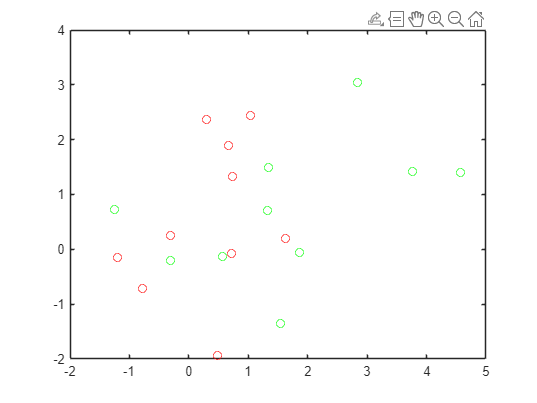

% Autor: Luis Eduardo Arenas Deseano
% Proyecto: Sistemas Inteligentes
% Descripción: Optimizacion Bayesiana para SVM
% Fecha: 1/12/2024

rng('default') % For reproducibility
grnpop = mvnrnd([1,0],eye(2),10);
redpop = mvnrnd([0,1],eye(2),10);

plot(grnpop(:,1),grnpop(:,2),'go')
hold on
plot(redpop(:,1),redpop(:,2),'ro')
hold off

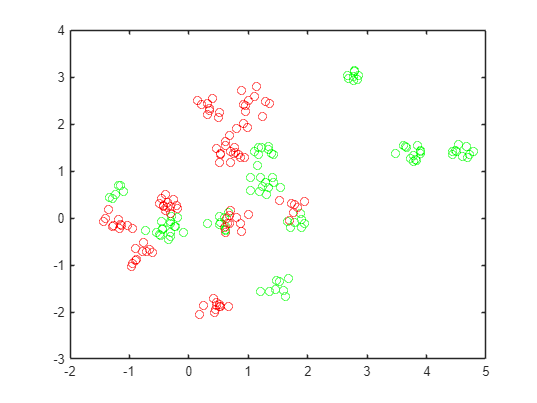


redpts = zeros(100,2);
grnpts = redpts;
for i = 1:100
    grnpts(i,:) = mvnrnd(grnpop(randi(10),:),eye(2)*0.02);
    redpts(i,:) = mvnrnd(redpop(randi(10),:),eye(2)*0.02);
end


figure
plot(grnpts(:,1),grnpts(:,2),'go')
hold on
plot(redpts(:,1),redpts(:,2),'ro')
hold off

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |       0.195 |     0.79289 |       0.195 |       0.195 |       193.54 |     0.069073 |        false |
|    2 | Accept |       0.345 |     0.12958 |       0.195 |     0.20398 |       43.991 |       277.86 |        false |
|    3 | Accept |       0.365 |    0.091577 |       0.195 |     0.20784 |    0.0056595 |     0.042141 |        false |
|    4 | Accept |        0.61 |     0.10862 |       0.195 |     0.31714 |       49.333 |    0.0010514 |         true |
|    5 | Best   |         0.1 |     0.18558 |   

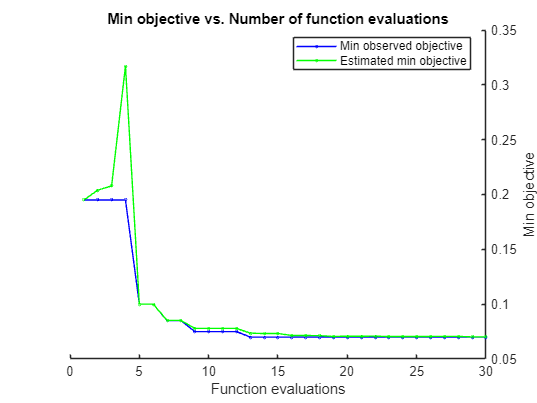

Mdl =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 200
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [66×1 double]
                                 Bias: -0.0911
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [200×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [200×1 logical]
                               Solver: 'SMO'


  Properties, Methods




cdata = [grnpts;redpts];
grp = ones(200,1);
grp(101:200) = -1;

c = cvpartition(200,'KFold',10);

opts = struct('CVPartition',c,'AcquisitionFunctionName', ...
    'expected-improvement-plus');
Mdl = fitcsvm(cdata,grp,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',opts)


Mdl.HyperparameterOptimizationResults.XAtMinEstimatedObjective

ans = 1×3 table
    BoxConstraint    KernelScale    Standardize
    _____________    ___________    ___________

       957.65          0.31271         false   



[x,CriterionValue,iteration] = bestPoint(Mdl.HyperparameterOptimizationResults)

x = 1×3 table
    BoxConstraint    KernelScale    Standardize
    _____________    ___________    ___________

       957.65          0.31271         false   


CriterionValue = 0.0724

iteration = 16


L_MinEstimated = kfoldLoss(fitcsvm(cdata,grp,'CVPartition',c, ...
    'KernelFunction','rbf','BoxConstraint',x.BoxConstraint, ...
    'KernelScale',x.KernelScale,'Standardize',x.Standardize=='true'))

L_MinEstimated = 0.0700


Mdl.HyperparameterOptimizationResults.XAtMinObjective

ans = 1×3 table
    BoxConstraint    KernelScale    Standardize
    _____________    ___________    ___________

       991.16          0.37801         false   



[x_observed,CriterionValue_observed,iteration_observed] = ...
    bestPoint(Mdl.HyperparameterOptimizationResults,'Criterion','min-observed')

x_observed = 1×3 table
    BoxConstraint    KernelScale    Standardize
    _____________    ___________    ___________

       991.16          0.37801         false   


CriterionValue_observed = 0.0700

iteration_observed = 13


d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(cdata(:,1)):d:max(cdata(:,1)), ...
    min(cdata(:,2)):d:max(cdata(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(Mdl,xGrid);

figure
h(1:2) = gscatter(cdata(:,1),cdata(:,2),grp,'rg','+*');
hold on
h(3) = plot(cdata(Mdl.IsSupportVector,1), ...
    cdata(Mdl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'},'Location','Southeast');

grnobj = gmdistribution(grnpop,.2*eye(2));
redobj = gmdistribution(redpop,.2*eye(2));

newData = random(grnobj,10);
newData = [newData;random(redobj,10)];
grpData = ones(20,1); % green = 1
grpData(11:20) = -1; % red = -1

v = predict(Mdl,newData);

L_Test = loss(Mdl,newData,grpData)

L_Test = 0.2000

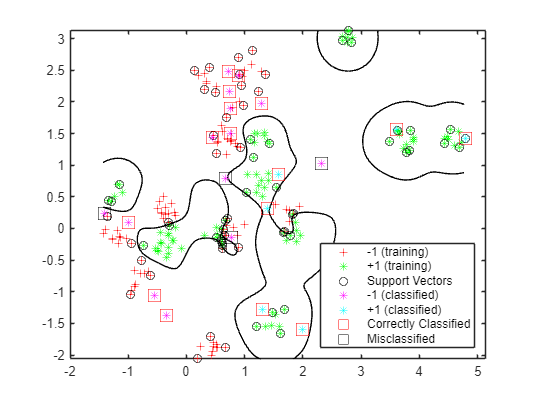


h(4:5) = gscatter(newData(:,1),newData(:,2),v,'mc','**');

mydiff = (v == grpData); % Classified correctly

for ii = mydiff % Plot red squares around correct pts
    h(6) = plot(newData(ii,1),newData(ii,2),'rs','MarkerSize',12);
end

for ii = not(mydiff) % Plot black squares around incorrect pts
    h(7) = plot(newData(ii,1),newData(ii,2),'ks','MarkerSize',12);
end
legend(h,{'-1 (training)','+1 (training)','Support Vectors', ...
    '-1 (classified)','+1 (classified)', ...
    'Correctly Classified','Misclassified'}, ...
    'Location','Southeast');
hold off